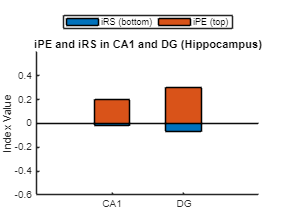

% Data
iPE = [0.2, 0.3];  % CA1, DG
iRS = [0.02, 0.07];

% Bar positions
x = [1, 2];  % 1 for CA1, 2 for DG

% Create the bar plot
figure;
hold on;

% Plot iRS values (mirrored, negative)
bar(x, -iRS, 0.5, 'FaceColor', [0 0.4470 0.7410]);  % Blue

% Plot iPE values
bar(x, iPE, 0.5, 'FaceColor', [0.8500 0.3250 0.0980]);  % Orange

% Customize axes
set(gca, 'XTick', x, 'XTickLabel', {'CA1', 'DG'});
ylabel('Index Value');
title('iPE and iRS in CA1 and DG (Hippocampus)');
ylim([-0.6, 0.6]);  % Adjust based on your data
yline(0, 'k');  % Line at y=0

% Add legend
legend('iRS (bottom)', 'iPE (top)', 'Location', 'northoutside', 'Orientation', 'horizontal');

hold off;